clc; clear;
u = symunit;



% Rør info
D = 8*u.mm;
D_t = 0.2*u.mm;
D_u = D;
D_i = D_u - D_t;

% Lamel info
B_kond = 36.5*u.cm;

H = 30*u.cm;
B = 6.5*u.cm;
N = 54; % antal huller
N_lam = 145;
lam_t = unitConvert(0.025*u.mm,"SI");

lam_mel = 3*u.mm;
h_lam_luft = 3*u.mm;

lam_t_tot = vpa(N_lam*lam_t,3)

$$lam\_t\_tot = 0.00362\,m$$


vpa(unitConvert(H*B,"SI"))

$$ans = 0.0195\,m^{2}$$

% Lamel areal og effektiv lamel radius
syms r_2eff

A_lam = 2*(H*B - N*pi/4 * D^2);
A_lam = vpa(unitConvert(A_lam,"SI"),4)

$$A\_lam = 0.03357\,m^{2}$$


A_lam2 = 2*N*pi*(r_2eff^2 - (D/2)^2);
A_lam2 = vpa(unitConvert(A_lam2,"SI"),4);

r_2eff_num = A_lam2 == A_lam;

r_2eff_num = solve(r_2eff_num, r_2eff);
r_2eff_num = vpa(unitConvert(r_2eff_num,"SI"),4)

$$r\_2eff\_num = \left(\begin{array}{c} -0.01072\,m\\ 0.01072\,m \end{array}\right)$$


% Lufteksponeret areal af rør
A_b = (B_kond - lam_t_tot) * D * N;
A_b = vpa(unitConvert(A_b, "SI"), 3)

$$A\_b = 0.156\,m^{2}$$


% Total overfladeareal af finner
A_t = N_lam*A_lam + A_b;
A_t = vpa(A_t, 5)

$$A\_t = 5.024\,m^{2}$$


A_lam*N_lam/A_b

$$ans = 31.181332518017945757817527890341$$

% Luftstrømshastighed
rho_luft = 1.028 * u.kg/u.m^3; % Luft ved 50C, fordi luften er 20 og r134 er 90 - filmtemp
A_1 = (H/2)^2*pi;
A_3 = H*B_kond;
A_2 = lam_mel * h_lam_luft * N_lam; % mellemrummet mellem hver lamel, snævreste tværsnit luften kommer gennem, antal lameller

%V_1 = 1*u.m/u.s;

syms V_2 V_1
V_3 = 10*u.m/u.s;


eq1 = rho_luft*A_1*V_1;
eq2 = rho_luft*A_2*V_2;
eq3 = rho_luft*A_3*V_3;

eq_c1 = eq1 == eq3;
eq_c2 = eq2 == eq3;

c = solve([eq_c1,eq_c2], [V_1,V_2])

c = struct with fields:
    V_1: (146/(3*pi))*([m]/[s])
    V_2: (730/87)*(([cm]^2*[m])/([mm]^2*[s]))


c_1 = vpa(unitConvert(c.V_1, "SI"), 4)

$$c\_1 = 15.49\,\frac{m}{s}$$

c_2 = vpa(unitConvert(c.V_2, "SI"), 4)

$$c\_2 = 839.1\,\frac{m}{s}$$


c2 = solve(eq_c2, V_2);
c2 = vpa(unitConvert(c2, "SI"), 4)

$$c2 = 839.1\,\frac{m}{s}$$

% Varmeovergangstal for luftsiden

lambda_luft = 0.0282*u.W/(u.m*u.K);
nu_luft = 17.90 * 10^(-6) * u.m^2/u.s;

C = 0.38 % 5 stk forsatte

C = 0.3800


syms alpha_f

Nu = alpha_f*D/lambda_luft;

Re = vpa(unitConvert(c_2*D/nu_luft, "SI"), 3)

$$Re = 3.75e+5$$


Nu2 = C*Re^(0.6)*(A_lam/A_b)^0.15;

alpha_f_eq = Nu == Nu2;

alpha_luft_num = solve(alpha_f_eq, alpha_f);
alpha_luft_num = vpa(unitConvert(alpha_luft_num, u.W/(u.m^2*u.K)), 4)

$$alpha\_luft\_num = 2351.0\,\frac{W}{K\,m^{2}}$$

% Lamel virkningsgrad
lambda_finne = 229 * u.W/(u.m*u.K);

m = sqrt((2*alpha_luft_num/(lambda_finne * lam_t)));
m = vpa(unitConvert(m, "SI"), 4)

$$m = 906.3\,\frac{1}{m}$$


r_1 = vpa(unitConvert(D/2,"SI"), 5)

$$r\_1 = 0.004\,m$$

r_2 = vpa(r_2eff_num(2), 5)

$$r\_2 = 0.010721\,m$$


C_2 = (2*r_1/m)/(r_2^2 - r_1^2);
C_2 = vpa(unitConvert(C_2, "SI"), 3)

$$C\_2 = 0.0892$$



eta_f = C_2*(besselk(1, m*r_1)*besseli(1, m*r_2) - besseli(1, m*r_1)*besselk(1, m*r_2))/(besseli(0, m*r_1)*besselk(1, m*r_2) + besselk(0, m*r_1)*besseli(1, m*r_2));
eta_f = vpa(unitConvert(eta_f, "SI"), 5)

$$eta\_f = 0.10084$$



% Overordnet lamelvirkningsgrad

eta_lamel_total = 1 - (N_lam*A_lam/A_t)*(1 - eta_f);
eta_lamel_total = vpa(eta_lamel_total, 4)

$$eta\_lamel\_total = 0.1288$$

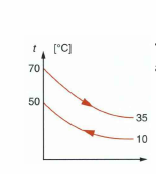

% Logaritmisk middel temperatur

t_fi = 90;    % Kølemiddel temp ind
t_fu = 30;    % Kølemiddel temp ud

t_lu = 30;    % Luft temp ind
t_li = 20;    % Luft temp ud

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li))*u.K;
T_LM = vpa(T_LM, 4)

$$T\_LM = 27.91\,K$$

% Modstande
% Indvendig varmeovergangsmodstand

A_i = pi*(D_i/2)^2;
alpha_i = 1470 * u.W/(u.m^2*u.K); % r134a

R_i = 1/(alpha_i * A_i);
R_i = vpa(unitConvert(R_i, u.K/u.W), 4)

$$R\_i = 14.24\,\frac{K}{W}$$


% Fra overleaf
%R_i = vpa((0.00391 * u.K/u.W),3)



% Varmeledningsmodstand i rørene
lambda_kobber = 372 * u.W/(u.m*u.K)

$$lambda\_kobber = 372\,\frac{W}{K\,m}$$

R_b = log(D_u/D_i)/(2*pi*D*lambda_kobber);
R_b = vpa(unitConvert(R_b, u.K/u.W), 4)

$$R\_b = 0.001354\,\frac{K}{W}$$


% Modstand for lamellerne og hele luftsiden

R_f = 1/(alpha_luft_num * A_t * eta_lamel_total);
R_f = vpa(unitConvert(R_f, u.K/u.W), 4)

$$R\_f = 0.0006574\,\frac{K}{W}$$


% Total modstand
R_tot = R_i + R_b + R_f

$$R\_tot = 14.238522768110097502124270522509\,\frac{K}{W}$$


% Vekslerens varmeydelse

Phi_veksler = T_LM/R_tot;
Phi_veksler = vpa(unitConvert(Phi_veksler, u.W), 10)

$$Phi\_veksler = 1.959861411\,W$$

CP = py.importlib.import_module("CoolProp.CoolProp")

CP =   Python module with properties:

                                             rebuildState: [1×1 py.builtin_function_or_method]
                                    LIST_STRING_DELIMITER: [1×1 py.int]
                                        DmassSmass_INPUTS: [1×1 py.int]
                                       INPUT_PAIR_INVALID: [1×1 py.int]
                          iisobaric_expansion_coefficient: [1×1 py.int]
                                                  PhaseSI: [1×1 py.builtin_function_or_method]
                               VTPR_ALWAYS_RELOAD_LIBRARY: [1×1 py.int]
                                            iphase_liquid: [1×1 py.int]
                                           DmolarT_INPUTS: [1×1 py.int]
                                                  ialphar: [1×1 py.int]
                                              iT_critical: [1×1 py.int]
                              iphase_supercritical_liquid


cp_r134_ind = vpa(CP.PropsSI("C","T",273.15+90,"Q",1,"R134a") * u.J/(u.kg),3)

$$cp\_r134\_ind = 3120.0\,\frac{J}{\mathrm{kg}}$$

cp_r134_ud = vpa(CP.PropsSI("C","T",273.15+30,"Q",0,"R134a") * u.J/(u.kg),3)

$$cp\_r134\_ud = 1450.0\,\frac{J}{\mathrm{kg}}$$



qmr = 0.00338*u.kg/u.s

$$qmr = \frac{169}{50000}\,\frac{\mathrm{kg}}{s}$$


Er134_ind = vpa(unitConvert(qmr * cp_r134_ind,"SI","Derived"),3)

$$Er134\_ind = 10.5\,W$$

Er134_ud = vpa(unitConvert(qmr * cp_r134_ud,"SI","Derived"),3)

$$Er134\_ud = 4.89\,W$$




A_i = vpa(pi*(D_i/2)^2,3)

$$A\_i = 47.8\,{\mathrm{mm}}^{2}$$


cp_r134_ind = vpa(CP.PropsSI("D","T",273.15+90,"Q",1,"R134a"),3)

$$cp\_r134\_ind = 217.0$$

cp_r134_ud = vpa(CP.PropsSI("D","T",273.15+30,"Q",0,"R134a"),3)

$$cp\_r134\_ud = 1190.0$$

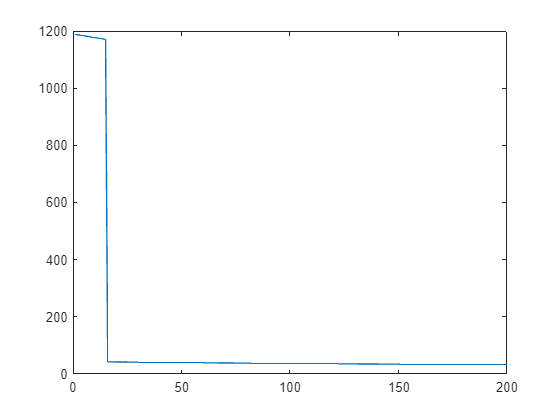


Tlin = linspace(30,90,200);
Dlin = zeros(1,length(Tlin));

for i = 1:length(Tlin)
    Dlin(i) = CP.PropsSI("D","T",273.15+Tlin(i),"P",8.7*1e5,"R134a");
end

plot(Dlin)



% Hastigheder gennem rør
% vs = qmr./(Dlin*A_i);
% vs = vpa(unitConvert(vs,"SI","derived"),3);
% vs = separateUnits(vs)








